# Praktikum 2 - Shift 1 Selasa 

`14 September 2021`

`Nama : Carolina Sinaga`

`NIM  : 10119050`

## Nomor 1

Amati grafik fungsi berikut !

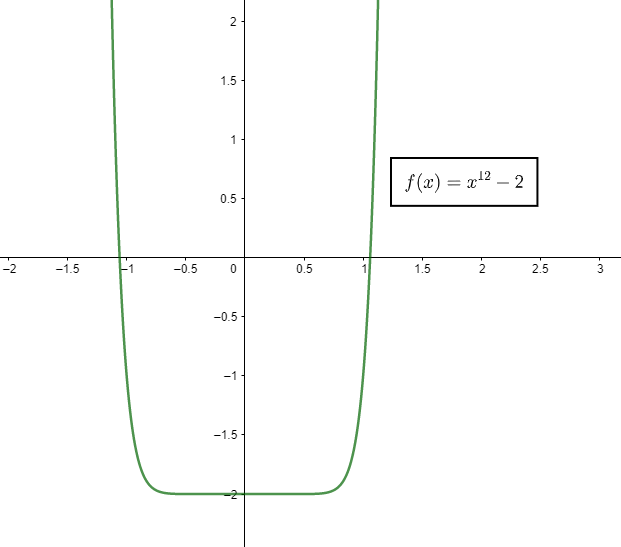

Diantara metode **bagi dua** dan metode **posisi palsu**, manakah yang lebih baik untuk mengaproksimasi akar dari fungsi tersebut? Sertakan alasan anda.

**Jawaban : Metode Bagi Dua, karena untuk fungsi di atas kekonvergenan fungsi dengan metode Bagi Dua lebih cepat dicapai dibandingkan menggunakan metode Posisi Palsu. **

**Dari grafik terlihat fungsi f(x) bersifat landai/datar, sehingga memperlambat kekonvergenan jika menggunakan Metode Posisi Palsu. **

## Nomor 2

Apa yang dimodifikasi dari metode **posisi palsu** sehingga menghasillkan metode **modifikasi posisi palsu/*****modified false position*** ? Mengapa modifikasi ini dilakukan?

**Jawaban : Yang dimodifikasi dari metode posisi palsu yaitu nilai fungsi pada iterasi berikutnya, dibuat menjadi setengah dari nilai fungsi pada iterasi sebelumnya. **

**Adanya Modifikasi Metode Posisi Palsu dikarenakan untuk fungsi tertentu, setelah dua atau lebih iterasi yang berurutan, salah satu ujung interval pengapit akar tidak mengalami perubahan. **

## Nomor 3

Pada tahun 2250, umat manusia sudah mengembangkan pesawat super cepat yang memungkinkan umat manusia untuk menjelajahi planet di galaksi nan jauh. 

Di planet Kronos pada kuadran Beta, diketahui konsentrasi oksigen di udara ($O_{\textrm{level}}$) berubah - ubah tergantung dengan temperatur planet saat itu. Terdapat hubungan

### 
$$\ln \left(O_{\textrm{level}} \right)=1\ldotp 08+\frac{77\ldotp 6}{T}-\frac{501\ldotp 2}{T^2 }+\frac{1980\ldotp 1}{T^3 }$$


dengan $T$ adalah temperatur planet (°C) dan $O_{\textrm{level}}$ konsentrasi oksigen di udara (satuan dalam %). 

Diketahui bahwa persamaan tersebut akurat untuk temperatur $T$ di interval $\left\lbrack 20,60\right\rbrack$ derajat Celsius.

### **3A**

Dengan menggunakan alat pengukur konsentrasi oksigen pada siang hari, diperoleh bahwa konsentrasi oksigen di udara saat itu  $O_{\textrm{level}} =21%$. 

Bangun sebuah fungsi inline (gunakan anonymous function) $f\left(T\right)=1\ldotp 08+\frac{77\ldotp 6}{T}-\frac{501\ldotp 2}{T^2 }+\frac{1980\ldotp 1}{T^3 }-\ln \left(O_{\textrm{level}} \right)$ dengan $O_{\textrm{level}} =21%$ dan bangun plot $f\left(T\right)$ untuk $T\in \left\lbrack 20,60\right\rbrack$

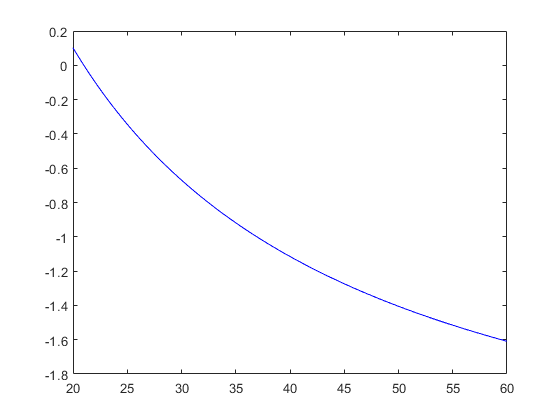

% Tulis jawaban anda dibawah garis
% --------------------------------
kons = @(T) 1.08 + 77.6/T - 501.2/(T^2) + 1980.1/(T^3);  % definisi ln(Olevel)
olevel = 21; % untuk Olevel  = 21%

x = linspace(20,60,100);        % merupakan interval suhu (T) 
f = @(T) (1.08 + 77.6./T - 501.2./(T.^2) + 1980.1./(T.^3)) - kons(olevel); % fungsi f(T)
y = f(x);
plot(x,y,'b')

### **3B**

Amati grafik pada bagian **3A**. Tentukanlah tebakan awal $a$ dan $b$ untuk menentukan akar dari $f\left(T\right)$dengan menggunakan **metode modifikasi posisi palsu,** dan jelaskan alasannya! (Asumsikan $a\le b$)

a = 20; % Tulis jawaban anda disini
b = 25; % Tulis jawaban anda disini

**Alasan : Pada grafik, f(T) bernilai nol pada interval [20, 25]**

### **3C**

Bangun fungsi pada file `ModFalsePos.m `yang menerima masukan berupa fungsi $f$, tebakan awal $a,b$ dan batas galat $\textrm{eps}$. 

Keluaran dari fungsi tersebut berupa hampiran nilai akar untuk fungsi $f$ menggunakan **metode modifikasi posisi palsu. **

(Gunakan $f$ yang sudah anda buat di bagian **3A)**

% Cek jawaban anda disini !
eps = 10^(-6);
T = ModFalsePos(f, a, b, eps);
fprintf("Jadi, nilai temperatur planet saat itu adalah %.4f derajat celsius.", T)

Jadi, nilai temperatur planet saat itu adalah 21.0000 derajat celsius.